# Pruebas para graficar el trébol estilizado

## Se crea la función del trebol

t = 0:0.01:2*pi;
rotacion = 1;
theta = pi*rotacion;
Escala = 1;
Amplitud = (5.3/4)*Escala;
Desplas = (6)*(Amplitud);
w = 4.0;
r2 = Desplas + Amplitud*cos(w*t+theta);
rotacion = 0;
theta = pi*rotacion;
r3 = Desplas + Amplitud*cos(w*t+theta);

figure()
polarplot(t, r2,'g');
hold on
polarplot(t, r3,'b');

## Dibujamos el cuadrado de 15*15

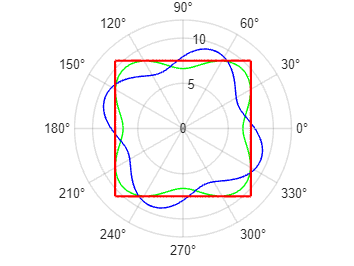

hold on
theta_der = -pi/4:0.01:pi/4;
theta_sup = pi/4:0.01:3*pi/4;

%Limite cuadrado
lim = 7.5*Escala;
r_der = lim./cos(theta_der);
r_sup = -lim./sin(theta_sup);


polarplot(theta_der, r_der, "-r", "LineWidth",1.6)
polarplot(theta_sup, r_sup, "-r", "LineWidth",1.6)
polarplot(-theta_der, r_sup, "-r", "LineWidth",1.6)
polarplot(-theta_sup, r_sup, "-r", "LineWidth",1.6)
hold off